# Plotting shaded 95% Confidence Intervals

*Created with R2022b. Compatible with R2021b and later releases*

I saw a [Reddit post](https://www.reddit.com/r/matlab/comments/wff8rk/plotting_shaded_95_confidence_intervals_using/) that asked:

"Hello! I am having trouble plotting my confidence intervals. Ideally I want to create a figure that looks like this where the mean is the solid line and the shaded region is the confidence intervals"

Let's give it a try.

We start with making up randomly generate data to play with. I am using integer for this, because it will make it easier to see what's going on later.

x = randi(100,[100,1]);
n = randn(100,1)*5;
y = 2*x + n;

We can the use [Curve Fitting Toolbox](https://www.mathworks.com/products/curvefitting.html) to [fit a curve](https://www.mathworks.com/help/curvefit/fit.html), and [plot it](https://www.mathworks.com/help/curvefit/cfit.plot.html) with confidence intervals. In this case, the confidence intervals are between two dotted lines.

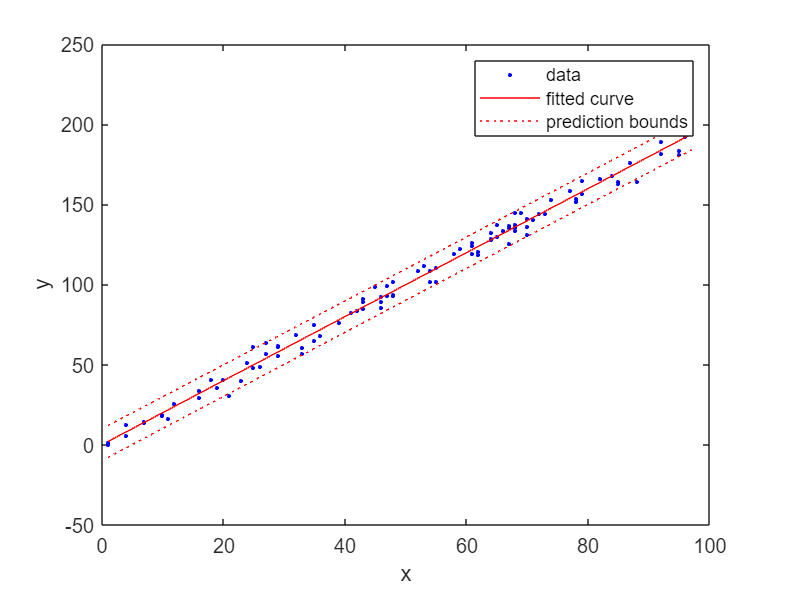

f = fit(x,y,'poly1');
figure
plot(f,x,y,'PredObs')

This is simple enough, but the OP wanted to use shaded intervals, like [this one](https://www.mathworks.com/help/matlab/creating_plots/line-plot-with-confidence-bounds.html).

You can use [predint](https://www.mathworks.com/help/curvefit/predint.html) to get confidence intervals.

ci = predint(f,x); 

And this should match exactly the confidence interval lines from Fig1.

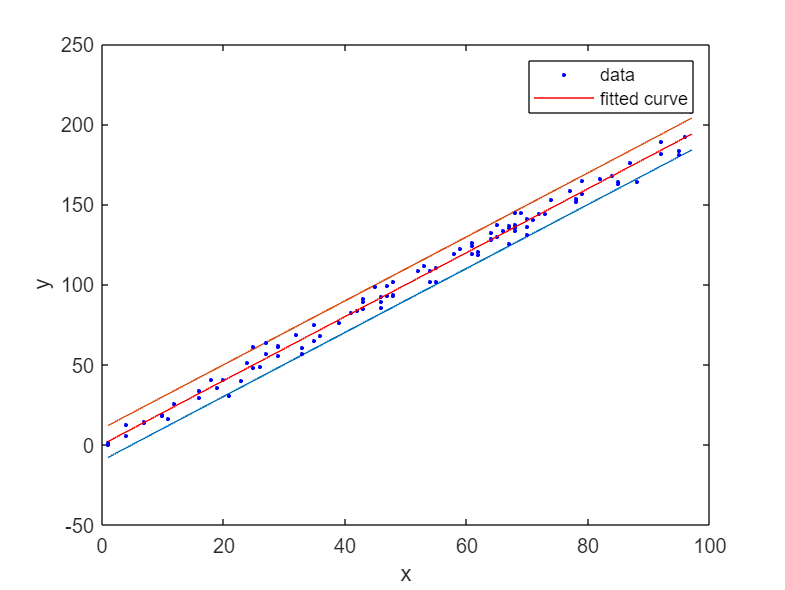

figure
plot(x, ci)
hold on
plot(f,x,y)

Now, we can use this to create a shaded area using [fill](https://www.mathworks.com/help/matlab/ref/fill.html), as shown in the documentation linked above.

One thing we need to understand is that fill expects vectors of x and y as input that define points in a polygon. So x should be lined up in such as way that define the points on x-axis that maps to the points in a polygon in the order that segments that form the polygon should line up.

That's not the case with the raw data we have, x. Therefore we need to generate a new `x` that orders the points in a sequence based on how the polygon should be drawn.

Our `x` ranges from 1 to 100 and has 100 elements, so we can define a new `xconf` that lines up the data in a sequence, and generate confidence intervals based on `xconf`.

xconf = (1:100)';
ci = predint(f,xconf);

However, this only defines one of the segments of the polygon from 1 to 100. We need another segment that covers the points from 100 to 1.

xconf = [xconf; xconf(100:-1:1)];

And ci already has two segments defined in two columns, so we just need to turn it into a vector by concatenating two columns.

yconf = [ci(:,1); ci(100:-1:1,2)];

Let's now plot the polygon.

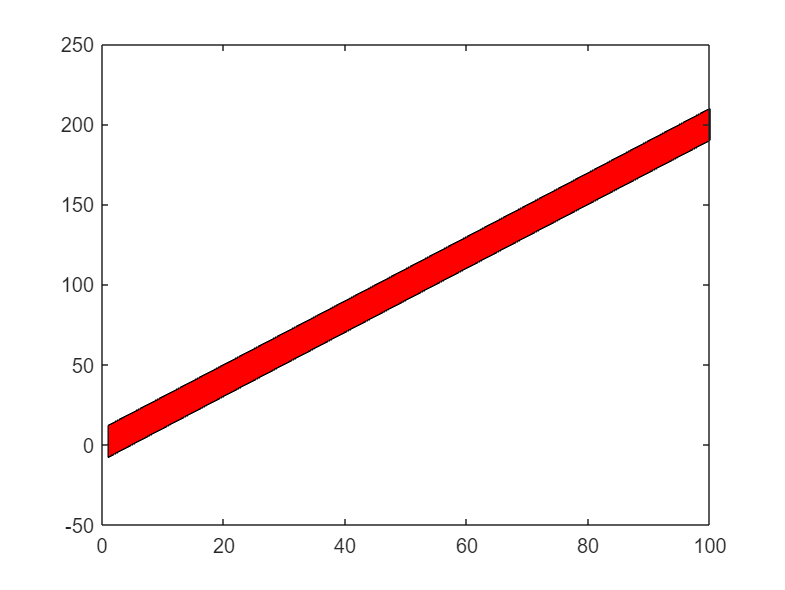

figure
p = fill(xconf,yconf,'red');

xconf and yconf correctly define the polygon we need. Now all we need to do is to overlay the actual data and make it look nicer.

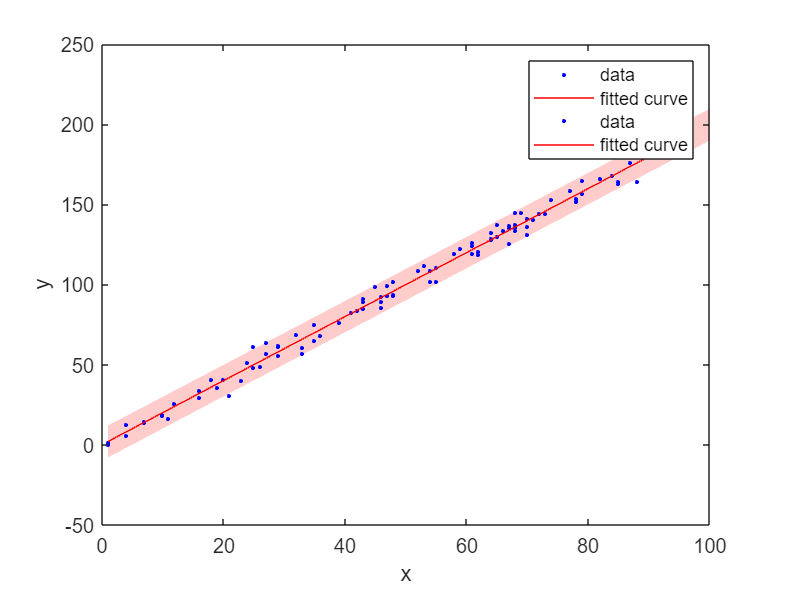

p.FaceColor = [1 0.8 0.8];      
p.EdgeColor = 'none';
hold on
plot(f,x,y)

*Copyright 2023 The MathWorks, Inc.*